Zerar workspace

clear;

Os dados originais (CSV) devem ter sido tratados previamente (editar a hora para o formato YYYY-MM-DD hh:mm:ss, adicionar linha de cabeçalho, verificar numero de colunas)

Importar CSV dos dados

node1 = readtable('logs/csv/coleta02_20170131_20170207/1/WMLOGB_edited.CSV');
node2 = readtable('logs/csv/coleta02_20170131_20170207/2/WMLOGB_edited.CSV');
node3 = readtable('logs/csv/coleta02_20170131_20170207/3/WMLOGB_edited.CSV');
node4 = readtable('logs/csv/coleta02_20170131_20170207/4/WMLOGB_edited.CSV');

Ajustando dados do sensor 03 do nó 4 (multiplicando por -1 para tornar os valores positivos)

*FIXME: muitas leituras do sensor 03 não foram feitas/armazenadas. Testar gerar o valor utilizando mediana ou outro método*

node4.sensor03value = node4.sensor03value * -1;
node4.sensor03value = median(node4{1:end,53:74},2,'omitnan');

Converter tabelas em timetables

node1 = table2timetable(node1);
node2 = table2timetable(node2);
node3 = table2timetable(node3);
node4 = table2timetable(node4);

Remoção de dados fora do escopo

% nó 1
%wmlog_node1([182:end],:) = [];
%wmlog_node1([1:15],:) = [];

% nó 2
%wmlog_node2([194:end],:) = [];
%wmlog_node2([1:21],:) = [];

% nó 4
%wmlog_node4([135:136],:) = [];
%wmlog_node4([1:14],:) = [];

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizando a formula que leva em consideração a temperatura do solo)

*Detalhe: a temperatura utilizada não é do solo, mas do sensor RTC*

% wmlog_node1.sensor01cbar = (3.213*(wmlog_node1.sensor01value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor01value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor02cbar = (3.213*(wmlog_node1.sensor02value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor02value./1000)-0.01205*wmlog_node1.temperature)
% wmlog_node1.sensor03cbar = (3.213*(wmlog_node1.sensor03value./1000)+4.093)./(1-0.009733*(wmlog_node1.sensor03value./1000)-0.01205*wmlog_node1.temperature)

Conversão dos dados dos sensores de Ohm para cbar/kPa (utilizanda a fórmula básica de conversão da irrometer)

node1.sensor01cbar = (node1.sensor01value-550)./137.5;
node1.sensor02cbar = (node1.sensor02value-550)./137.5;
node1.sensor03cbar = (node1.sensor03value-550)./137.5;

node2.sensor01cbar = (node2.sensor01value-550)./137.5;
node2.sensor02cbar = (node2.sensor02value-550)./137.5;
node2.sensor03cbar = (node2.sensor03value-550)./137.5;

node3.sensor01cbar = (node3.sensor01value-550)./137.5;
node3.sensor02cbar = (node3.sensor02value-550)./137.5;
node3.sensor03cbar = (node3.sensor03value-550)./137.5;

node4.sensor01cbar = (node4.sensor01value-550)./137.5;
node4.sensor02cbar = (node4.sensor02value-550)./137.5;
node4.sensor03cbar = (node4.sensor03value-550)./137.5;

Determinar período de tempo a ser utilizado e filtrar tabelas

%range = timerange('2017-01-31', '2017-02-07');
%node1 = node1(range,:);
%node2 = node2(range,:);
%node4 = node4(range,:);

TESTE: ajustes de escala (nós 1 e 2 estão em uma ordem de grandeza maior, não sei o motivo)

node1.sensor01cbar = node1.sensor01cbar/100;
node2.sensor01cbar = node2.sensor01cbar/100;

AJUSTE TEMPORÁRIO: converter outliers do nó 3 em NaN

node3.sensor02cbar(1) = NaN;
node3.sensor02cbar(2) = NaN;
node3.sensor02cbar(23) = NaN;
node3.sensor02cbar(24) = NaN;
node3.sensor02cbar(25) = NaN;
node3.sensor02cbar(26) = NaN;

Determinar variáveis para plotar linhas de indicação de umidade do solo

DateStrings = {'2017-01-31';'2017-02-08'};
t = datetime(DateStrings,'InputFormat','yyyy-MM-dd');

Plotar dados dos sensores de 15cm

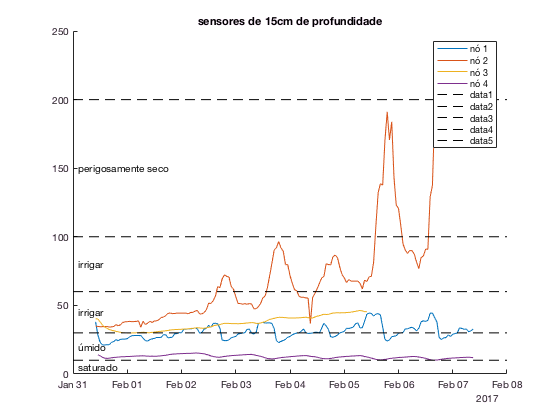

figure
hold on
plot(node1.time,node1.sensor01cbar,'DisplayName','nó 1')
plot(node2.time,node2.sensor01cbar,'DisplayName','nó 2')
plot(node3.time,node3.sensor01cbar,'DisplayName','nó 3')
plot(node4.time,node4.sensor01cbar,'DisplayName','nó 4')
text(0.1,5,'saturado')
plot(t,[10 10], 'k--'); % 0 a 10: solo saturado
text(0.1,20,'úmido');
plot(t,[30 30], 'k--'); % 10 a 30: solo adequadamente umido (exceto areia fina)
text(0.1,45,'irrigar');
plot(t,[60 60], 'k--'); % 30 a 60: necessita rega
text(0.1,80,'irrigar');
plot(t,[100 100], 'k--'); % 60 a 100: necessita rega (barro pesado)
text(0.1,150,'perigosamente seco');
plot(t,[200 200], 'k--'); % 100 a 200: perigosamente seco
hold off
legend('show')
title('sensores de 15cm de profundidade')

Plotar dados dos sensores de 45cm

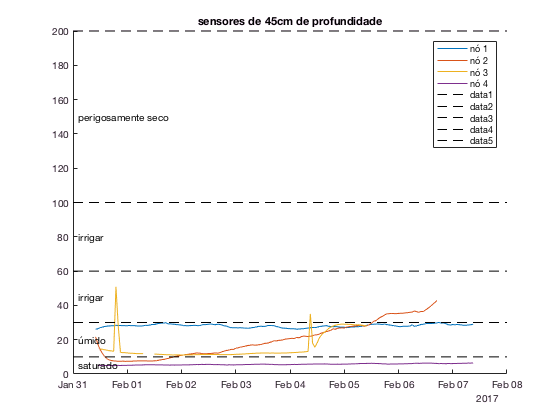

figure
hold on
plot(node1.time,node1.sensor02cbar,'DisplayName','nó 1')
plot(node2.time,node2.sensor02cbar,'DisplayName','nó 2')
% nó 3
% existem outliers em:
% 2017-01-31 10:00:00
% 2017-01-31 11:00:00
% 2017-02-01 09:00:00
% 2017-02-01 10:00:00
% 2017-02-01 11:00:00
plot(node3.time,node3.sensor02cbar,'DisplayName','nó 3')
plot(node4.time,node4.sensor02cbar,'DisplayName','nó 4')
text(0.1,5,'saturado')
plot(t,[10 10], 'k--'); % 0 a 10: solo saturado
text(0.1,20,'úmido');
plot(t,[30 30], 'k--'); % 10 a 30: solo adequadamente umido (exceto areia fina)
text(0.1,45,'irrigar');
plot(t,[60 60], 'k--'); % 30 a 60: necessita rega
text(0.1,80,'irrigar');
plot(t,[100 100], 'k--'); % 60 a 100: necessita rega (barro pesado)
text(0.1,150,'perigosamente seco');
plot(t,[200 200], 'k--'); % 100 a 200: perigosamente seco
hold off
legend('show')
title('sensores de 45cm de profundidade')

Plotar dados dos sensores de 75cm

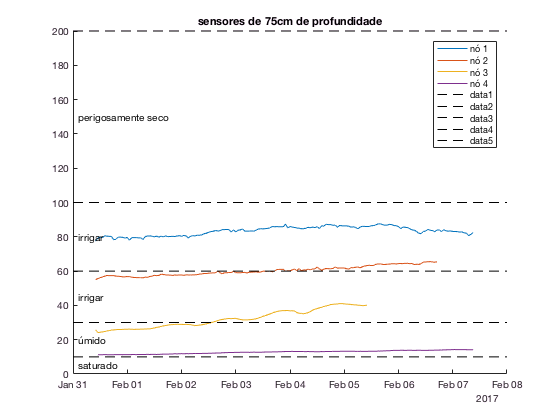

figure
hold on
plot(node1.time,node1.sensor03cbar,'DisplayName','nó 1')
plot(node2.time,node2.sensor03cbar,'DisplayName','nó 2')
plot(node3.time,node3.sensor03cbar,'DisplayName','nó 3')
plot(node4.time,node4.sensor03cbar,'DisplayName','nó 4')
text(0.1,5,'saturado')
plot(t,[10 10], 'k--'); % 0 a 10: solo saturado
text(0.1,20,'úmido');
plot(t,[30 30], 'k--'); % 10 a 30: solo adequadamente umido (exceto areia fina)
text(0.1,45,'irrigar');
plot(t,[60 60], 'k--'); % 30 a 60: necessita rega
text(0.1,80,'irrigar');
plot(t,[100 100], 'k--'); % 60 a 100: necessita rega (barro pesado)
text(0.1,150,'perigosamente seco');
plot(t,[200 200], 'k--'); % 100 a 200: perigosamente seco
hold off
legend('show')
title('sensores de 75cm de profundidade')